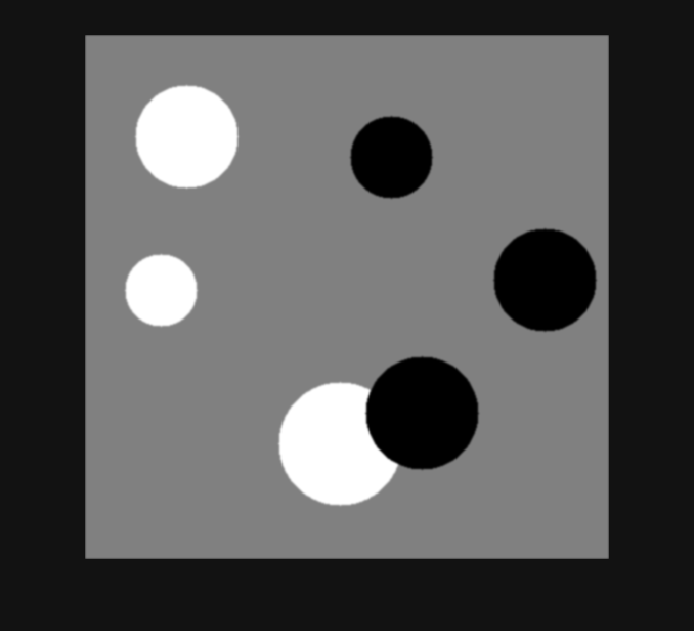

clear all;
close all;

%img = imread('coins.png'); % 15-30
img = imread('circlesBrightDark.png'); % 30-65
gray = im2gray(img);
imshow(gray);

Get the outlines of circles

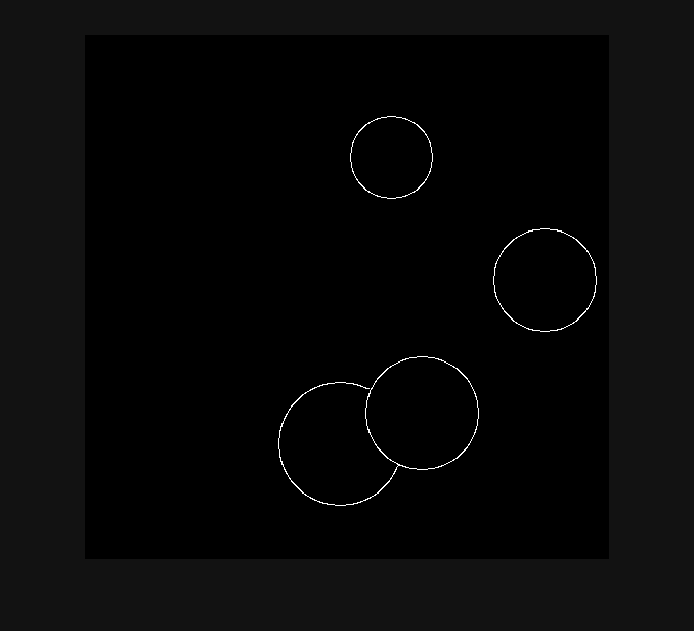

BW1 = edge(img, 'Canny', 0.5);
imshow(BW1);

Find centers and radius of circles

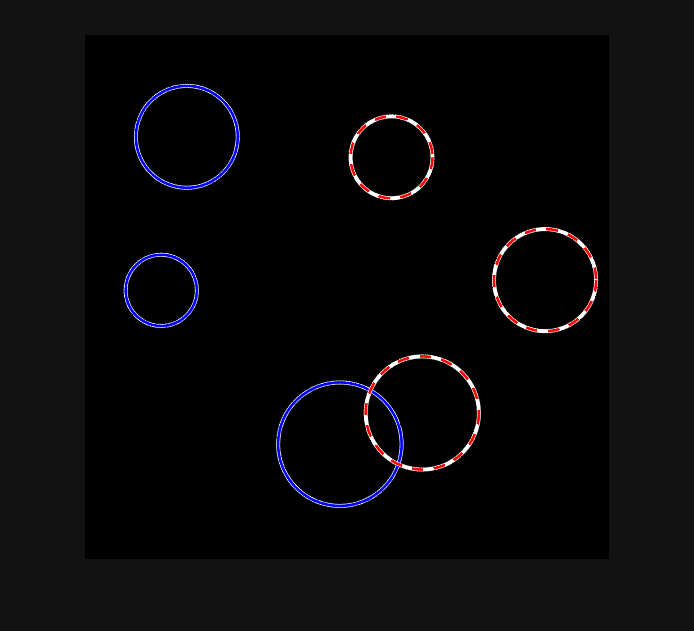

Rmin = 30;
Rmax = 65;
% Find bright objects
[centersBright, radiiBright] = imfindcircles(img, [Rmin Rmax], 'ObjectPolarity', 'bright');
% Find dark objects
[centersDark, radiiDark] = imfindcircles(img, [Rmin Rmax], 'ObjectPolarity', 'dark');
viscircles(centersBright, radiiBright, 'EdgeColor', 'b');
viscircles(centersDark, radiiDark, 'EdgeColor', 'r', 'LineStyle', '--');